clear all

%
% ------------ consts --------------
dt = 1.66e-9;
omega = 6e7;
PermE = 8.854e-12;
PermH = 12.566e-7;

dx = 1;
dy = 1;
dz = 1;

dimX = 30;
dimY = 30;
dimZ = 30;
Tcells = dimX*dimY*dimZ;
[x,y,z] = meshgrid(linspace(1,dx*dimX,dimX),linspace(1,dy*dimY,dimY),linspace(1,dz*dimZ,dimZ));

% % boundry thickness
B_tk = 2;

% % temporary boundry zone to be used to be set to 0 
% should cause rflections since lack of PML but in the case of 
% a simple plane wave there should be no major diffrence 
BC = (x>dx*(dimX-B_tk)|(x <= dx*B_tk)|(y>dy*(dimY-B_tk))|(y <= dy*B_tk)|(z>dz*(dimZ-B_tk)))|(z <= dz*B_tk);

Souce = (x == dx*(dimX-B_tk-1));

nx = 10;
ny = 10;
nz = 10;
dim = 100;

% % subsample points for quiver3
[xn,yn,zn] = meshgrid(linspace(0,dx*dimX,nx), linspace(0,dy*dimY,ny), linspace(0,dz*dimZ,nz));

xslice = [ 4 27];   
yslice = 25;
zslice = 15;
%-----------PML------------------------------------------
xB = clip(abs(x-dimX*dx/2)-(dimX-B_tk)*dx/2,0,99999);
xB = xB./max(xB);
xB = (3-2*xB).*xB.*xB;

yB = clip(abs(y-dimY*dy/2)-(dimY-B_tk)*dy/2,0,99999);
yB = yB./max(yB);
yB = (3-2*yB).*yB.*yB;

zB = clip(abs(z-dimZ*dz/2)-(dimZ-B_tk)*dz/2,0,99999);
zB = zB./max(zB);
zB = (3-2*zB).*zB.*zB;

%----------------spatial deretives creation---------------
% % matrices are sparse to conserve memory 
% % consider !Q! from tests

C1 = false(dimX,dimY,dimZ);
C1 = permute(C1,[2 1 3]);
C1(end,:,:) = true;
Dy = spdiags([-1*C1([(dimX):end ones(1,dimX-1)]') ones(Tcells,1) -1*(~C1([1 1:end-1]'))],[-dimX+1 0 1],Tcells,Tcells);
Dy = -1*Dy;
[sum(abs(Dy*x(:))) sum(abs(Dy*y(:))) sum(abs(Dy*z(:)))]

ans =            0       52200           0


C1 = false(dimX,dimY,dimZ);
C1 = permute(C1,[2 1 3]);
C1(:,end,:) = true;
Dx = spdiags([-1*C1([((dimX-1)*dimY+1):end ones(1,(dimX-1)*dimY)]') ones(Tcells,1) -1*(~C1([1:dimY 1:end-dimY]'))],[-(dimX-1)*dimY 0 dimY],Tcells,Tcells);
Dx = -1*Dx;
[sum(abs(Dx*x(:))) sum(abs(Dx*y(:))) sum(abs(Dx*z(:)))]

ans =        52200           0           0


C1 = false(dimX,dimY,dimZ);
C1 = permute(C1,[2 1 3]);
C1(:,end,:) = true;
Dz = spdiags([-ones(Tcells,1) ones(Tcells,1) -ones(Tcells,1)],[-Tcells+dimX*dimY 0 dimY*dimX],Tcells,Tcells);
Dz = -1*Dz;
[sum(abs(Dz*x(:))) sum(abs(Dz*y(:))) sum(abs(Dz*z(:)))]

ans =            0           0       52200


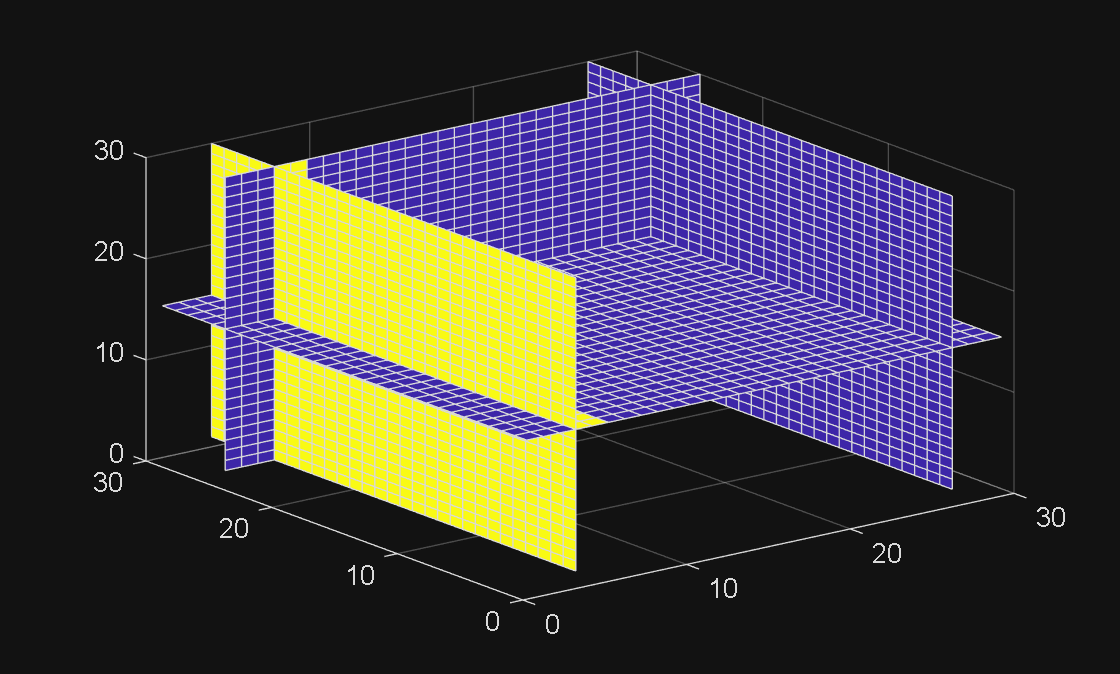



Dx = .5*(Dx-Dx');
Dy = .5*(Dy-Dy');
Dz = .5*(Dz-Dz');
%------------ field creation ---------------

R = [x(:) y(:) z(:)];

% % ~(set random field)
if true 
E = zeros(dimX,dimY,dimZ,3);
H = zeros(dimX,dimY,dimZ,3);
else
E = rand(100,100,100,3).*2-1;
B = rand(100,100,100,3).*2-1;
end



EMag = [];
HMag = [];

Gt = @(t) .5*exp(-(5*(t-5)).^2);

%------- GPU if avaliable --------------

% if gpuDeviceCount>0
% R = gpuArray(R);
% E = gpuArray(E);
% H = gpuArray(H);
% Dx = gpuArray(Dx);
% Dy = gpuArray(Dy);
% Dz = gpuArray(Dz);
% end

T_gpu = 1;
% -------------- video ------------

% % set file path for video file for it to work


% v = VideoWriter('C:\Users\srk2687\peaks_animation.avi'); 
% open(v);

%--------------- main loop --------------------

for t=0:1200

% % runs few loops on GPU to maximize utilization due to slow transfer speeds
% recommended to tune T_gpu for spesific device and resolution
for t_g=1:T_gpu

% E(Souce(:),3) = cos((t*T_gpu+t_g)*dt*omega);
% E(1,:,:,3) = cos((t*T_gpu+t_g)*dt*omega);
% H(1:dimX*dimY,1) = cos(t*dt*omega);
% H(end/2,3) = sin(t*dt*omega);

% % temporarly set boundry condtions to 0 to observe effects with fixed
% boundry 
% will be used later for PML
% E(BC(:),:) = 0; 
% H(BC(:),:) = 0; 
% 
% E(:,1) = E(:,1) - dt*PermH*(Dy *H(:,3)-Dz *H(:,2));
% E(:,2) = E(:,2) - dt*PermH*(Dz *H(:,1)-Dx *H(:,3));
% E(:,3) = E(:,3) - dt*PermH*(Dx *H(:,2)-Dy *H(:,1));
% 
% E(BC(:),:) = 0; 
% H(BC(:),:) = 0; 
% 
% H(:,1) = H(:,1) + dt*PermE*(Dy *E(:,3)-Dz *E(:,2));
% H(:,2) = H(:,2) + dt*PermE*(Dz *E(:,1)-Dx *E(:,3));
% H(:,3) = H(:,3) + dt*PermE*(Dx *E(:,2)-Dy *E(:,1));

H(:,1:4,:,2) = H(:,1:4,:,2) + Gt(t);


[C_x,C_y,C_z] = curl(x,y,z,E(:,:,:,1),E(:,:,:,2),E(:,:,:,3));
H = H + dt*PermH .* cat(4,C_x,C_y,C_z);
[C_x,C_y,C_z] = curl(x,y,z,H(:,:,:,1),H(:,:,:,2),H(:,:,:,3));
E = E - dt*PermE .* cat(4,C_x,C_y,C_z);

end

% % needed for pushing gpu VRAM arrays back to RAM
if gpuDeviceCount>0
En = reshape(gather(E(:)),[dimX dimY dimZ 3]);
Hn = reshape(gather(H(:)),[dimX dimY dimZ 3]);
else
En = reshape(E(:),[dimX dimY dimZ 3]);
Hn = reshape(H(:),[dimX dimY dimZ 3]);
end

En = E;
Hn = H;

% % L2 norm squared to get rough approx of energy in system
EMag(t+1) = sum((En(:)).^2);
HMag(t+1) = sum((Hn(:)).^2);

% % display Vector field as quiver or slice
if false

% % subsampling to create cleaner visulization for quiver3
En = En(1:(dimX/nx):dimX,1:(dimX/ny):dimX,1:(dimX/nz):dimX,:);
Hn = Hn(1:(dimX/nx):dimX,1:(dimX/ny):dimX,1:(dimX/nz):dimX,:);

% % vector field with E and H field colored R and G respectively 
quiver3(xn,yn,zn,En(:,:,:,1),En(:,:,:,2),En(:,:,:,3),'r')
hold on;
quiver3(xn+.5*dimX/nx,yn+.5*dimX/ny,zn+.5*dimX/nz,Hn(:,:,:,1),Hn(:,:,:,2),Hn(:,:,:,3),'g')
% % visulize poynying
% quiver3(xn,yn,zn,P(:,:,:,1),P(:,:,:,2),P(:,:,:,3),'w')
hold off;

%prevent grid jitter in video of quiver
ax = gca; % Get the current axes handle
    xlim(ax, [0 dx*dimX]); % Set x-axis limits
    ylim(ax, [0 dy*dimY]); % Set y-axis limits
    zlim(ax, [0 dz*dimZ]); % Set z-axis limits
view(3)
else
% % ^.3 is used as a quick tonemap due to uncertienty in actual value that
% need to be mesured 
P = vecnorm(E,2,4);
slice(x,y,z,clip(P,0,5),xslice,yslice,zslice);
end

drawnow;

% writeVideo(v, mat2gray(squeeze(En(2,:,:,:))))

end

% close(v);


function appoxEnergyPlot()
semilogy(1:size(EMag,2),EMag,'g');
hold on;
semilogy(1:size(HMag,2),HMag,'r');
hold off;
end




